# Taller 1, punto 4: perceptron sobre las particiones de Iris

Dos problemas de dos clases: A) setosa vs resto B) versicolor vs virginica

clear; close all; clc
load iris_splits.mat

## Parametros

regla = 3; umbral = 0; salida = [-1 1]; max_epocas = 200; semilla = 1;
alphas = [0.01 0.05 0.1 0.5 1];
problemas = {'A: setosa vs resto', 'B: versicolor vs virginica'};

## Entrenamiento en las cuatro particiones y los cinco alpha

R = table();
for pr = 1:2
    for k = 1:4
        if pr == 1
            Xtr = S(k).Xtr; Xte = S(k).Xte;
            dtr = 2*(S(k).ytr == 1) - 1;  dte = 2*(S(k).yte == 1) - 1;
        else
            mtr = S(k).ytr ~= 1; mte = S(k).yte ~= 1;
            Xtr = S(k).Xtr(mtr,:); Xte = S(k).Xte(mte,:);
            dtr = 2*(S(k).ytr(mtr) == 2) - 1;  dte = 2*(S(k).yte(mte) == 2) - 1;
        end
        % escalado min-max con los valores del entrenamiento
        mn = min(Xtr); mx = max(Xtr);
        Xtr = (Xtr - mn) ./ (mx - mn);  Xte = (Xte - mn) ./ (mx - mn);
        for a = alphas
            [w, b, ep, conv] = perceptron(Xtr, dtr, regla, a, umbral, salida, max_epocas, semilla);
            acc_tr = 100*mean(predecir(Xtr, w, b, umbral, salida) == dtr);
            acc_te = 100*mean(predecir(Xte, w, b, umbral, salida) == dte);
            R = [R; table(problemas(pr), {sprintf('%d-%d', 100*S(k).p, 100-100*S(k).p)}, a, ep, conv, acc_tr, acc_te, ...
                 'VariableNames', {'Problema','Particion','Alpha','Epocas','Convergio','Exact_train','Exact_test'})];
        end
    end
end
R

R = 40×7 table
           Problema           Particion    Alpha    Epocas    Convergio    Exact_train    Exact_test
    ______________________    _________    _____    ______    _________    ___________    __________

    {'A: setosa vs resto'}    {'60-40'}    0.01       17        true           100           100    
    {'A: setosa vs resto'}    {'60-40'}    0.05        5        true           100           100    
    {'A: setosa vs resto'}    {'60-40'}     0.1        4        true           100           100    
    {'A: setosa vs resto'}    {'60-40'}     0.5        2        true           100           100    
    {'A: setosa vs resto'}    {'60-40'}       1        2        true           100           100    
    {'A: setosa vs resto'}    {'70-30'}    0.01       15        true           100           100    
    {'A: setosa vs resto'}    {'70-30'}    0.05        5        true           100           100    
    {'A: setosa vs resto'}    {'70-30'}     0.1        4        true       

## Exactitud en test contra alpha

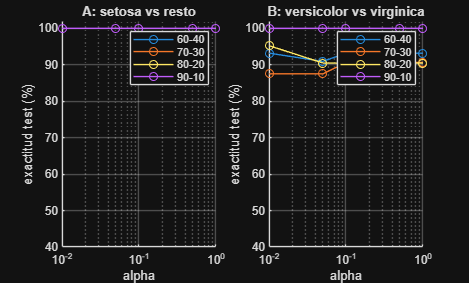

figure
for pr = 1:2
    subplot(1,2,pr); hold on
    for k = 1:4
        m = strcmp(R.Problema, problemas{pr}) & strcmp(R.Particion, sprintf('%d-%d', 100*S(k).p, 100-100*S(k).p));
        plot(R.Alpha(m), R.Exact_test(m), '-o', 'DisplayName', R.Particion{find(m,1)});
    end
    set(gca, 'XScale', 'log'); grid on; ylim([40 102]); legend
    xlabel('alpha'); ylabel('exactitud test (%)'); title(problemas{pr});
end

## Por que no converge el problema B

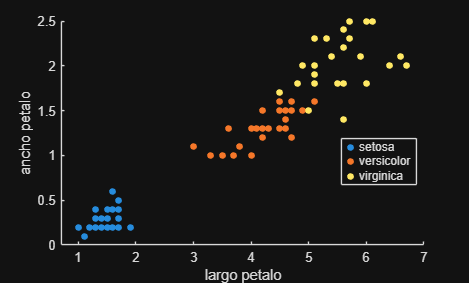

figure
gscatter(S(1).Xtr(:,3), S(1).Xtr(:,4), S(1).ytr)
xlabel('largo petalo'); ylabel('ancho petalo'); legend('setosa','versicolor','virginica')